TN=tencom(y,u,r,init,varargin)

------------- Tensor completion given the inputs, outputs, TT-ranks, and TT initialization with scalar inputs

y = Outputs,

u = Inputs,

r = TT-ranks,

init = TT initialization.

Reference ---------

Fast and Accurate Tensor Completion with Tensor Trains: A System Identification Approach

clear all
load Data_mnist
tic
p=1

p = 1

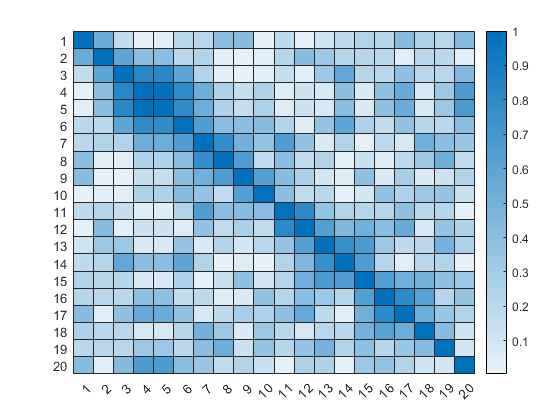

featurez=feature{p}(1:60000, :);    tfeaturez=feature{p}(60000+1:end,:);
J=10;

a = featurez;
Covz = corr(featurez);
Z= 1-abs(Covz);
[optima, distas] = findorder(Z);
featurez = featurez(:,optima');
Z = corr(featurez);
heatmap(abs(Z));


tfeaturez = tfeaturez(:,optima');

% labelos = 6*(rflabels+1)-1;
labelos = 5*(rflabels+1)

labelos =      0     0     0     0     0    10     0     0     0     0
    10     0     0     0     0     0     0     0     0     0
     0     0     0     0    10     0     0     0     0     0
     0    10     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0    10
     0     0    10     0     0     0     0     0     0     0
     0    10     0     0     0     0     0     0     0     0
     0     0     0    10     0     0     0     0     0     0
     0    10     0     0     0     0     0     0     0     0
     0     0     0     0    10     0     0     0     0     0


y = labelos(:);


[N1, d1]=size(featurez); 
d=d1+1;
N=N1*J;

nn = 1;  %degree B-spline
knotintervals = 1;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (featurez/knotdist)-indexes+1;
for i=1:d1
bn = inputs(:,i).^[nn:-1:0]*M;

ub{i} = zeros(N1,nnn);
for ii=1:N1
   ub{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end


u{1} = kron(eye(10),ones(N1,1));
for i=1:d1
u{i+1} = repmat(ub{i},J,1);
end



Pcount = (nnn)^d

Pcount = 2097152

gamma=((N/Pcount^4))

gamma = 3.1019e-20

% gamma=0

R = nnn^2;
r=R*ones(1,d+1);
r(1) = 1; r(2)=J; r(3)=5;   r(d-1)=nnn^2; r(d)=nnn; r(d+1)=1;
disp(r)

     1    10     5     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     2     1




n=[J nnn*ones(1,d)];

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

MAXITR = d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated


 tic

% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
   
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex},u{sweepindex},Vp{sweepindex});
        g=pinv(A'*A)*(A'*y);
     
%         D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));        
%         g=pinv(A'*A + gamma*D)*(A'*y);


        
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        toc
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        toc
                    end
                end
    
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-y)^2/2; % check residual
            res2(itr)=gamma/2*(g'*g);
           
            if (itr>4)
                if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
                 disp(res1(itr))
                 break;
                end
            end
            
            itr=itr+1; %update iteration
        end   

        
end  

Elapsed time is 4.044716 seconds.


Elapsed time is 7.402636 seconds.


Elapsed time is 11.481056 seconds.


Elapsed time is 14.842126 seconds.


Elapsed time is 18.937219 seconds.


Elapsed time is 22.309697 seconds.


Elapsed time is 26.460738 seconds.


Elapsed time is 30.008705 seconds.


Elapsed time is 34.263049 seconds.


Elapsed time is 37.652192 seconds.


Elapsed time is 41.722375 seconds.


Elapsed time is 45.127573 seconds.


Elapsed time is 49.217214 seconds.


Elapsed time is 52.731156 seconds.


Elapsed time is 57.117547 seconds.


Elapsed time is 60.664503 seconds.


Elapsed time is 64.778876 seconds.


Elapsed time is 68.141100 seconds.


Index in position 2 exceeds array bounds (must not exceed 8).

plot(res1)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;
for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 2:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i-1}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,J);
V(1)= G(1);
for jj=1:Nt   
f = squeeze(V{1});
for i = 2:length(G)
f = f*V{i}(:,:,jj);
end
output(jj,:)=f';
end


[~,ind] = max(output,'',2)
plot(output(:,10))

plot(output(289,:))

ind=ind-1
test_err=sum(ind ~= tlabels)/10000

Conf = confusionmat(tlabels,ind);
confusionchart(Conf);






% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end




for numro=1:J

itis= (tlabels == (numro-1));
tota=sum(itis);
testlabels = 11*(itis);
erboi = output(:,numro)-testlabels;
relerror(numro) = sum(abs(erboi))/sum(testlabels);
end

plot(relerror)
histogram((erboi)')

% plot(output-rflabels)
plot(output-testlabels)

sum(abs(output-testlabels))

relerror = sum(abs(erboi))/sum(testlabels)

sum(abs(output-testlabels)<3)



kiko = output(testlabels==10)-10
sum(kiko<-10)
plot(kiko)
